# Beer's Law Example

This example shows how to compute an extinction coefficient $k_\lambda$ at a given wavenumber $\lambda$ using absorbance spectra $A_\lambda$ of known concentrations $c$.  The Beer's law relationship is$ck_\lambda = A_\lambda$.

Copyright 2022 Battelle Memorial Institute

## The Data

Load the napalm data.

clearvars
load pnnl_napalm_data
whos

  Name                     Size               Bytes  Class     Attributes

  A_train                 20x1713            274080  double              
  A_unknown               12x1713            164448  double              
  C_train                 20x3                  480  double              
  C_validation            12x3                  288  double              
  ConcentrationUnits       1x4                    8  char                
  ConstituentNames         1x3                  364  cell                
  WavenumberLabel          1x20                  40  char                
  Wavenumbers              1x1713             13704  double              



The concentration matrix $C_\textrm{train}$ contains the percent by weight of each of 20 solutions in the training data.  The columns correspond to benzene, polystyrene, and gasolene.


$$C_\textrm{train} = %
\begin{array}{rl}%
\begin{array}{c}%
\begin{array}{rrr}%
\textit{benzene} & \textit{polystyrene} & \textit{gasoline} \\%
\end{array}\\%
\left[%
\begin{array}{rrr}%
         0  &       0 & 100.0000\\%
    5.1309  &       0 &  94.8691\\%
   10.0660  &       0 &  89.9300\\%
   20.1799  &       0 &  79.8201\\%
   40.0120  &       0 &  59.9878\\%
   59.9972  &       0 &  40.0028\\%
   79.8412  &       0 &  20.1588\\%
   89.8273  &       0 &  10.1727\\%
  100.0000  &       0 &        0\\%
   90.0264  &  9.9736 &        0\\%
   80.1375  & 19.8625 &        0\\%
   64.9950  & 35.0005 &        0\\%
   28.0000  & 48.0000 &  23.0000\\%
   49.9507  &  5.0599 &  44.9895\\%
   40.0182  & 20.0385 &  39.9433\\%
   40.0154  & 10.0036 &  49.9810\\%
   30.0059  & 10.0282 &  59.9659\\%
   40.0340  & 39.9670 &  19.9990\\%
   49.9393  &  3.3748 &  46.6859\\%
   46.6501  & 13.4658 &  39.8840\\%
\end{array}%
\right]%
\end{array}%
&%
\begin{array}{r}%
\\%
1\\%
2\\%
3\\%
4\\%
5\\%
6\\%
7\\%
8\\%
9\\%
10\\%
11\\%
12\\%
13\\%
14\\%
15\\%
16\\%
17\\%
18\\%
19\\%
20\\%
\end{array}%
\end{array}%
$$


The absorbance spectra for each of the 20 solutions in the training data are the rows of $A_\textrm{train}$.

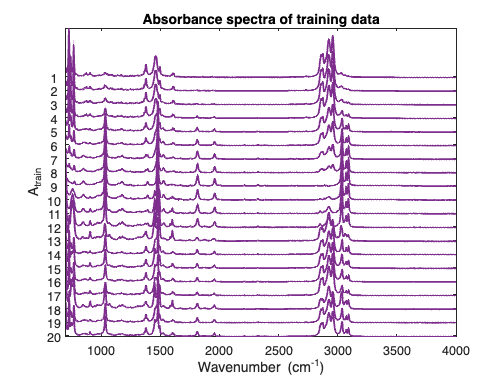

pnnl_napalm_plot_training_spectra

## Pure Spectra

Look at the rows of $C_\textrm{train}$ and you can see that row 9 is pure benzene and row 1 is pure gasolene.  A pure spectra of polystyrene is inferred from a combination of rows 12 and 9.


$$$$
C_\textrm{train}([1,\, 9,\, 12],\;:\;) = %
\begin{array}{rl}%
\begin{array}{c}%
\begin{array}{rrr}%
\textit{benzene} & \textit{polystyrene} & \textit{gasoline} \\%
\end{array}\\%
\left[%
\begin{array}{rrr}%
         0  &       0 & 100.0000\\%
  100.0000  &       0 &        0\\%
   64.9950  & 35.0005 &        0\\%
\end{array}%
\right]%
\end{array}%
&%
\begin{array}{r}%
\\%
1\\%
9\\%
12\\%
\end{array}%
\end{array}%
$$
$$


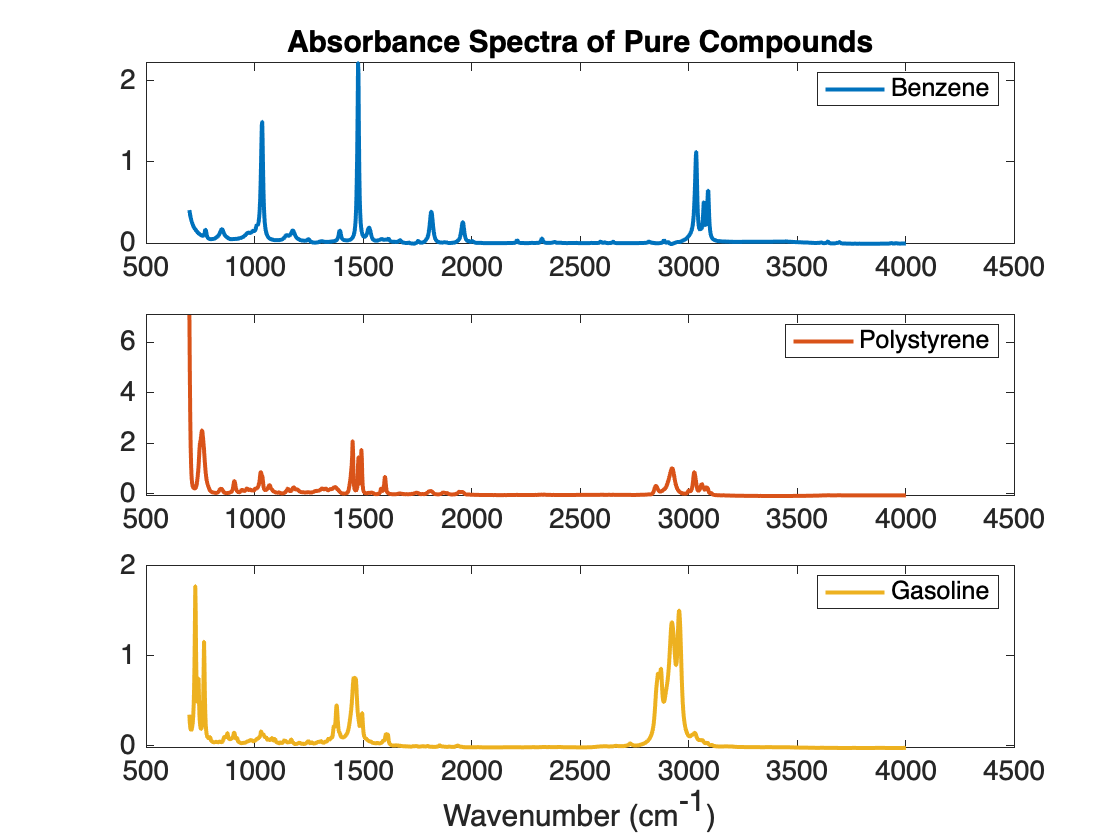

A_pure = pnnl_napalm_pure_spectra;
pnnl_napalm_plot_pure_spectra

## Locate the best index for benzene

Plot the absorbances with `1:m` as the x-axis so you can find the index that corresponds to the best peak for each of the constituents.

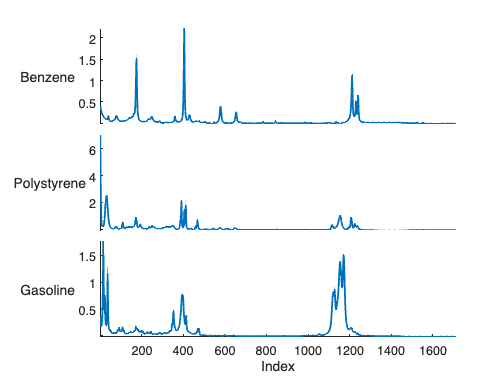

m = size(A_pure,2);
figure
stackedplot(1:m,A_pure','LineWidth',2,'FontSize',14,'DisplayLabels',ConstituentNames);
xlabel('Index')

Hover over the plot to examine the peaks of the benzene spectrum.   The largest peak in the benzene spectrum seems like the natural one to choose, but there are peaks in the other spectra coinciding with the largest peak, so choose the second largest peak to examine.  It has index 175.  This corresponds to wavenumber $\lambda_{175} = 1035.587$.

index = 175;
lambda = Wavenumbers(index)

lambda = 1.0356e+03

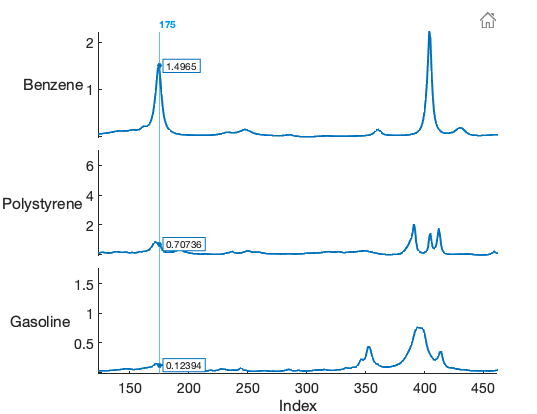

## Beer's Law for Benzene

Pull out the concentration column for benzene and the absorbtion column for $\lambda_{175} = 1035.587 \textrm{cm}^{-1}$.

c_benzene = C_train(:,1);
A_lambda = A_train(:,index);

Compute the extinction coefficient $k_{\lambda_{175}}$ for benzene for wavenumber $\lambda_{175} = 1035.587 \textrm{cm}^{-1}$ that best fits the following equation.  The fit won't be exact because, for example, looking at the first row there is no value that makes $0\cdot k_{\lambda_{175}} = 0.1239$ true.  However, we can compute a value for $k_{\lambda_{175}}$ that minimizes the sum of squares of the difference $c_\textrm{benzene} \cdot k_{\lambda_{175}} - A_{\lambda_{175}}$ (hence the name "least squares").


$$$$
\begin{array}{cccc}
c_\textrm{benzene} & & & A_{\lambda_{175}}\\
\left[%
\begin{array}{r}%
         0\\%
    5.1309\\%
   10.0660\\%
   20.1799\\%
   40.0120\\%
   59.9972\\%
   79.8412\\%
   89.8273\\%
  100.0000\\%
   90.0264\\%
   80.1375\\%
   64.9950\\%
   28.0000\\%
   49.9507\\%
   40.0182\\%
   40.0154\\%
   30.0059\\%
   40.0340\\%
   49.9393\\%
   46.6501\\%
\end{array}%
\right]%
&
k_{\lambda_{175}}
&
\approx
&
\left[%
\begin{array}{r}%
    0.1239\\%
    0.1801\\%
    0.2207\\%
    0.3423\\%
    0.6381\\%
    0.8222\\%
    1.1272\\%
    1.3174\\%
    1.4965\\%
    1.4311\\%
    1.3286\\%
    1.2203\\%
    0.5492\\%
    0.6973\\%
    0.6603\\%
    0.5863\\%
    0.4573\\%
    0.8525\\%
    0.6905\\%
    0.7131\\%
\end{array}%
\right]%
\end{array}
$$
$$


MATLAB's backslash operator computes the least-squares solution to $c_\textrm{benzene} \cdot k_\lambda = A_\lambda$.

k_lambda = c_benzene \ A_lambda

k_lambda = 0.0156

Plot the measured absorbtion vs the least-squares best fit $A_\lambda = c k_\lambda$.

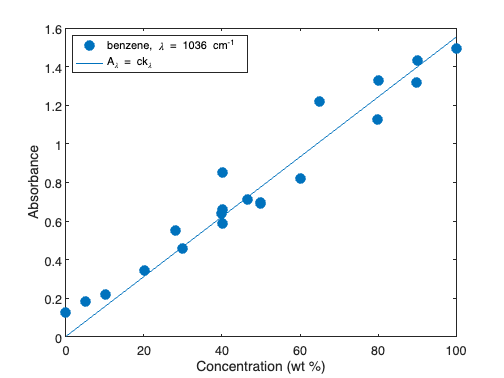

figure;
plot(c_benzene,A_lambda,'.','MarkerSize',35)
colorOrder = pnnl_colorOrder(1);
hold on
plot(c_benzene, c_benzene*k_lambda,'Color',colorOrder(1,:))
legend(sprintf('benzene, \\lambda = %d cm^{-1}',round(lambda)),'A_\lambda = ck_\lambda','Location','northwest')
xlabel('Concentration (wt %)')
ylabel('Absorbance')
set(gca,'FontSize',14)

## Choose peaks for the remaining constituents

Choose bands for each constituent that meet the following criteria:

- High intensity

- Don't have high overlap with bands from other constituents.

The following bands for benzene, polystyrene, and gasoline, respectively, met those criteria, but we did not do an exhaustive search.  There might be others that are more optimal.

wavenumber_index = [175, 468, 1128];
wavenumbers_of_interest = Wavenumbers(wavenumber_index)

wavenumbers_of_interest = 1.0e+03 *

    1.0356    1.6006    2.8734


Plot the chosen peaks in each spectra.

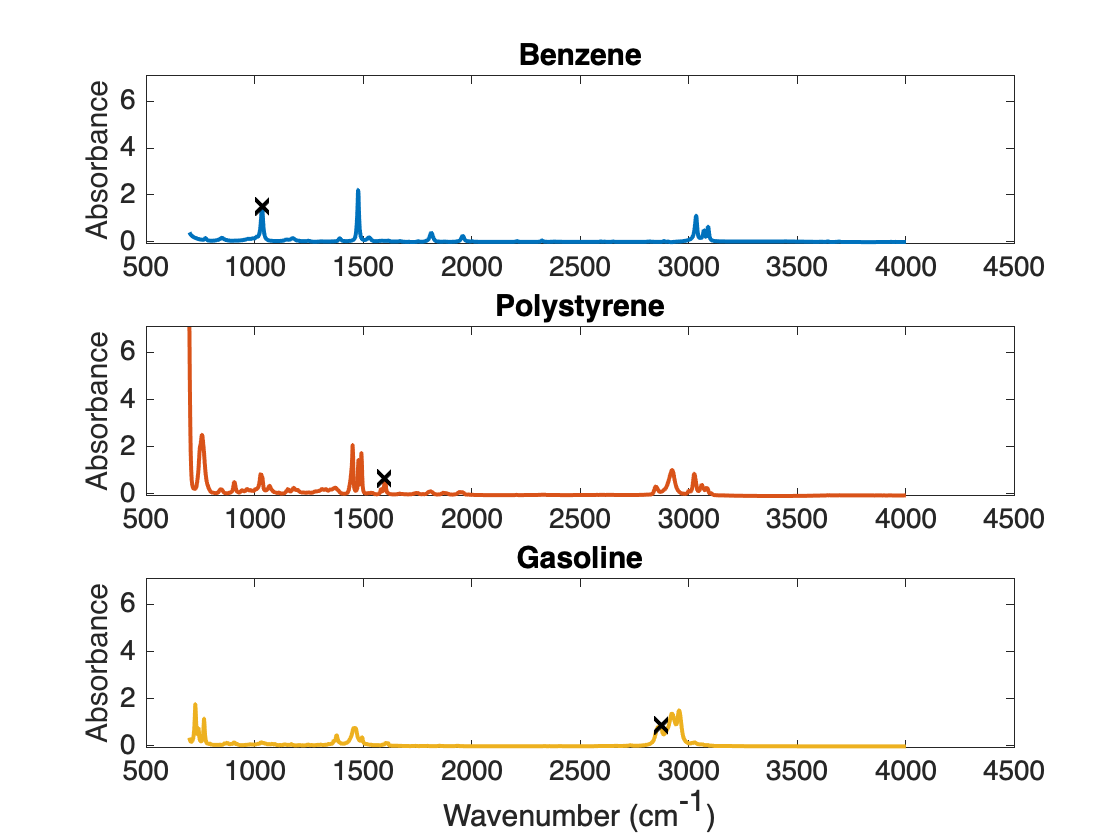

n = size(C_train,2);
colorOrder = pnnl_colorOrder(n);
figure;
h = gobjects(1,n);
for j = 1:n
    h(j) = subplot(n,1,j);
    plot(Wavenumbers,A_pure(j,:),'LineWidth',2,'Color',colorOrder(j,:));
    hold on
    plot(Wavenumbers(wavenumber_index(j)),A_pure(j,wavenumber_index(j)),'xk','MarkerSize',8,'LineWidth',2);
    title(ConstituentNames{j})
    ylabel('Absorbance')
end
linkaxes(h)
xlabel(WavenumberLabel)
set(h,'FontSize',14)

## Repeat for each of the other spectra

Repeat the process for computing extinction coefficients $k_\lambda$  for each of the other spectra and plot the results.

k_lambda = zeros(1,n);
for j = 1:n
    k_lambda(j) = C_train(:,j) \ A_train(:,wavenumber_index(j));
end

The extinction coefficients are for benzene, polystyrene, and gasolene respectively.

k_lambda

k_lambda =     0.0156    0.0076    0.0098


## Cross Validation

Cross-validate by running CLS for each of the rows in the training set, leaving one row out, and using that row as the unknown data. 

p = size(C_train,1);
C_cross_validation = zeros(p,n);
for i = 1:p
    for j = 1:n
        C_cross_validation(i,j) = pnnl_cls(A_train([1:i-1,i+1:p],wavenumber_index(j)),C_train([1:i-1,i+1:p],j),A_train(i,wavenumber_index(j)));
    end
end


## Compute Root Mean Square Errors

RMSEC = zeros(1,n);
RMSECV = zeros(1,n);
RMSEP = zeros(1,n);
for j = 1:n
    RMSEC(j) = pnnl_rmse(A_train(:,wavenumber_index(j))/k_lambda(j), C_train(:,j));
    RMSECV(j) = pnnl_rmse(C_cross_validation(:,j), C_train(:,j));
    RMSEP(j) = pnnl_rmse(A_unknown(:,wavenumber_index(j))/k_lambda(j), C_validation(:,j));
end
pnnl_display_rmse("Beer's Law",ConstituentNames,RMSEC,RMSECV,RMSEP)

--------------------------------------------------
Beer's Law       Benzene   Polystyrene      Gasoline
   RMSEC        6.4301        5.7474         9.215
  RMSECV        6.7929        5.7984        9.7963
   RMSEP        11.073        2.2007        25.387
--------------------------------------------------


## Plot the results

Plot the results with lines of best fit.

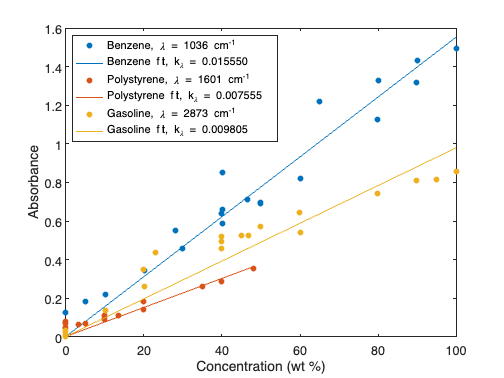

figure;
colorOrder = pnnl_colorOrder(n);
legend_string = cell(1,2*n);
legend_number = 0;
for j = 1:n
    plot(C_train(:,j),A_train(:,wavenumber_index(j)),'o',...
        'MarkerEdgeColor',colorOrder(j,:),...
        'MarkerFaceColor',colorOrder(j,:),...
        'DisplayName',sprintf('%s, \\lambda = %d cm^{-1}',ConstituentNames{j},round(wavenumbers_of_interest(j))))
    hold on
    plot(C_train(:,j), C_train(:,j)*k_lambda(j),'Color',colorOrder(j,:),...
        'DisplayName',sprintf('%s fit, k_{\\lambda} = %f',ConstituentNames{j},k_lambda(j)))
end
legend('Location','northwest')
xlabel('Concentration (wt %)')
ylabel('Absorbance')
set(gca,'FontSize',14)

Disclaimer

This material was prepared as an account of work sponsored by an agency of the United States Government. Neither the United States Government nor the United States Department of Energy, nor Battelle, nor any of their employees, nor any jurisdiction or organization that has cooperated in the development of these materials, makes any warranty, express or implied, or assumes any legal liability or responsibility for the accuracy, completeness, or usefulness or any information, apparatus, product, software, or process disclosed, or represents that its use would not infringe privately owned rights.

Reference herein to any specific commercial product, process, or service by trade name, trademark, manufacturer, or otherwise does not necessarily constitute or imply its endorsement, recommendation, or favoring by the United States Government or any agency thereof, or Battelle Memorial Institute. The views and opinions of authors expressed herein do not necessarily state or reflect those of the United States Government or any agency thereof.

PACIFIC NORTHWEST NATIONAL LABORATORY

operated by

BATTELLE

for the

UNITED STATES DEPARTMENT OF ENERGY

under Contract DE-AC05-76RL01830